clear all;

m1 = 2500; %kg
m2 = 320; %kg
k1 = 80000; %N/m
k2 = 500000; %N/m
b1 = 350; % Ns/m
b2 = 15020; %Ns/m

s = tf('s');
G1 = ((m1+m2)*s^2+b2*s+k2)/((m1*s^2+b1*s+k1)*(m2*s^2+(b1+b2)*s+(k1+k2))-(b1*s+k1)*(b1*s+k1))

G1 =
 
                  2820 s^2 + 15020 s + 500000
  ------------------------------------------------------------
  800000 s^4 + 3.854e07 s^3 + 1.481e09 s^2 + 1.377e09 s + 4e10
 
Continuous-time transfer function.



G2 = (-m1*b2*s^3-m1*k2*s^2)/((m1*s^2+b1*s+k1)*(m2*s^2+(b1+b2)*s+(k1+k2))-(b1*s+k1)*(b1*s+k1))

G2 =
 
                  -3.755e07 s^3 - 1.25e09 s^2
  ------------------------------------------------------------
  800000 s^4 + 3.854e07 s^3 + 1.481e09 s^2 + 1.377e09 s + 4e10
 
Continuous-time transfer function.



[G1_num,G1_den] = tfdata(G1)

G1_num = 1×1 cell array
    {[0 0 2820 15020 500000]}


G1_den = 1×1 cell array
    {[800000 38537000 1.4809e+09 1.3766e+09 4.0000e+10]}


[G2_num,G2_den] = tfdata(G2)

G2_num = 1×1 cell array
    {[0 -37550000 -1.2500e+09 0 0]}


G2_den = 1×1 cell array
    {[800000 38537000 1.4809e+09 1.3766e+09 4.0000e+10]}


nums = [G1_num,G2_num]

nums = 1×2 cell array
    {[0 0 2820 15020 500000]}    {[0 -37550000 -1.2500e+09 0 0]}


dens = [G1_den,G2_den]

dens = 1×2 cell array
    {[800000 38537000 1.4809e+09 1.3766e+09 4.0000e+10]}    {[800000 38537000 1.4809e+09 1.3766e+09 4.0000e+10]}


sys = tf(nums,dens)

sys =
 
  From input 1 to output:
                  2820 s^2 + 15020 s + 500000
  ------------------------------------------------------------
  800000 s^4 + 3.854e07 s^3 + 1.481e09 s^2 + 1.377e09 s + 4e10
 
  From input 2 to output:
                  -3.755e07 s^3 - 1.25e09 s^2
  ------------------------------------------------------------
  800000 s^4 + 3.854e07 s^3 + 1.481e09 s^2 + 1.377e09 s + 4e10
 
Continuous-time transfer function.



sysss = ss(sys)

sysss =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       0  -12.21
   x2      16       0       0  -6.722
   x3       0       8       0  -57.85
   x4       0       0      32  -48.17
 
  B = 
              u1         u2
   x1  1.907e-05          0
   x2  9.167e-06          0
   x3  1.377e-05     -6.104
   x4          0     -5.867
 
  C = 
       x1  x2  x3  x4
   y1   0   0   0   8
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



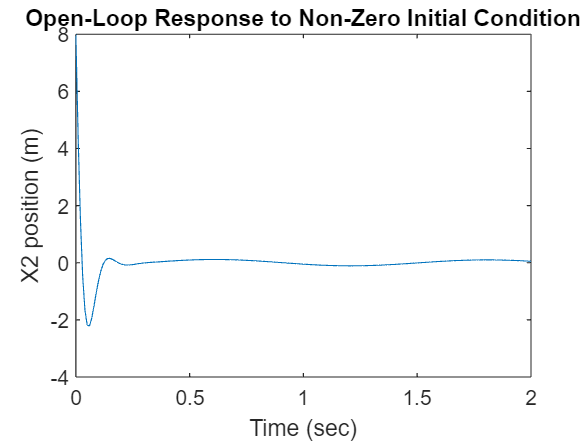


t = 0:0.01:2;
u = zeros(2,length(t));
x0 = [0 0 0 1];
[y,t,x] = lsim(sysss,u,t,x0);
plot(t,y)
title('Open-Loop Response to Non-Zero Initial Condition')
xlabel('Time (sec)')
ylabel('X2 position (m)')